clear; close all; clc;

# **Fase 2**

**Comum a todos os cenários**

quick = false;         % quando estivcer tudo bom, coloco a false para fazer mais simulações
rng('default');        % repoe o gerador
snr_db = 0:2:40;
if quick, D12 = 50;   D512 = 3;
else,     D12 = 2000; D512 = 200; end
T12 = 50;  T512 = 10;
niveis12  = [-40 -35 -30];   % variancia do erro de estimacao [dB], 16 antenas
niveis512 = [-55 -50 -45];   % idem, 512 antenas

# Teste: erro nulo reproduz a Fase 1

rng(1);
Rt = simula_cenario(16, ones(1,16), 2000, 50, snr_db, 4, 0);
i  = find(snr_db == 20);
fprintf('Capacidade a 20 dB, ZF | SVD | BD: %.3f  %.2f  %.3f   (Fase 1: 87.698  148.57  93.895)\n', Rt.C(i,1:3));

Capacidade a 20 dB, ZF | SVD | BD: 87.698  148.57  93.895   (Fase 1: 87.698  148.57  93.895)


fprintf('MMSE: %.3f\n', Rt.C(i,4));

MMSE: 95.712


fprintf('IUI mediana [dB], ZF | SVD | BD | MMSE: %s\n', mat2str(squeeze(10*log10(median(Rt.IUI(:,i,:),1)))', 3));

IUI mediana [dB], ZF | SVD | BD | MMSE: [-273 -289 -291 -26.8]


# Cenários

### Cenário 1 A

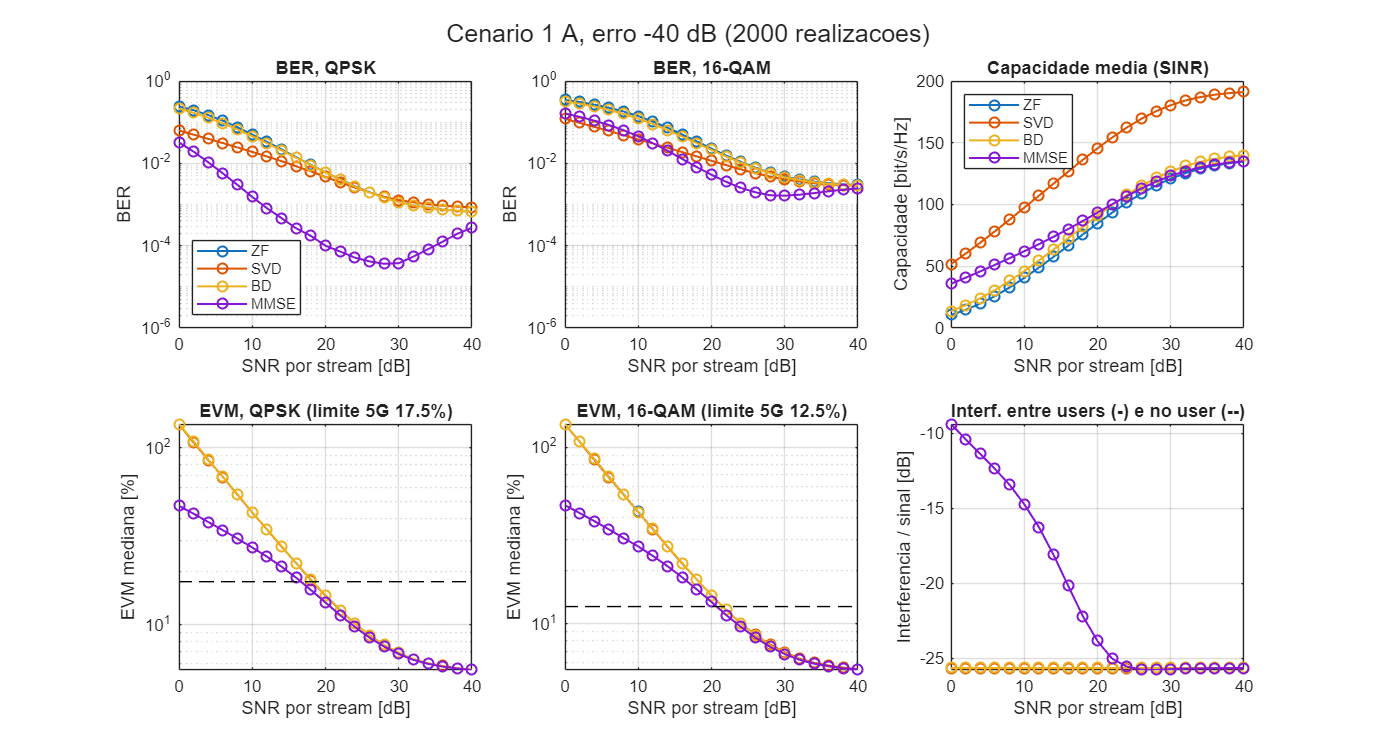

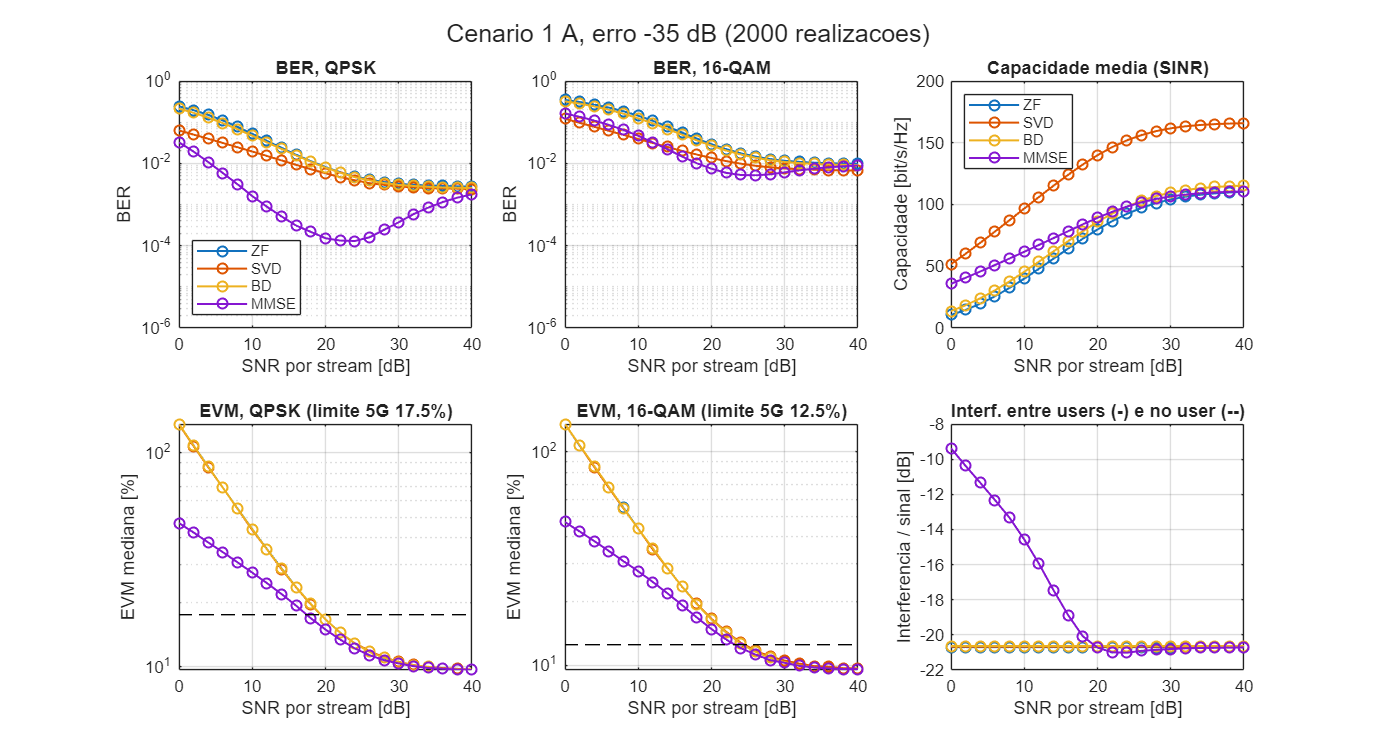

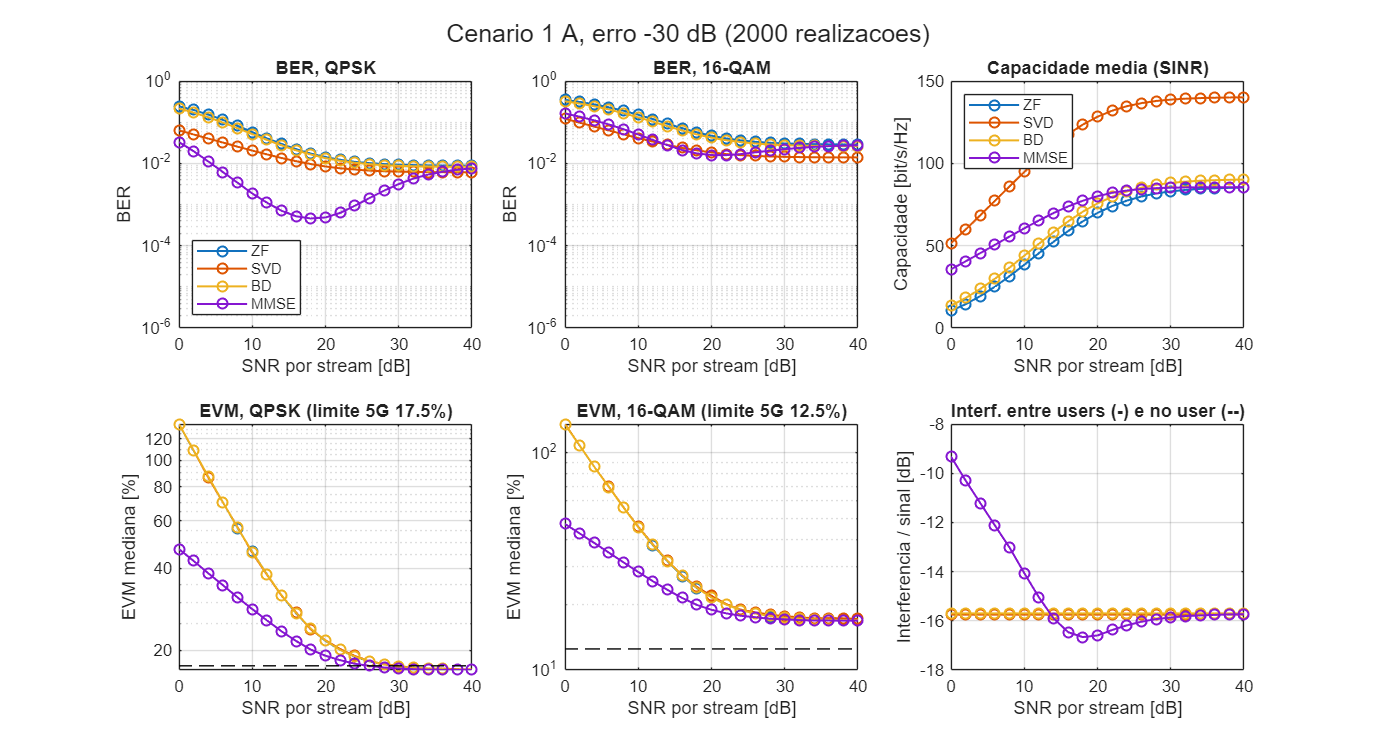

rng(1);
Nt = 16;  sizes = ones(1,16);
R4_1A = cell(1,3);  R16_1A = cell(1,3);
for L = 1:3
    sig_e2 = 10^(niveis12(L)/10);
    rng(1);  R4_1A{L}  = simula_cenario(Nt, sizes, D12, T12, snr_db, 4,  sig_e2);
    rng(1);  R16_1A{L} = simula_cenario(Nt, sizes, D12, T12, snr_db, 16, sig_e2);
    plota_fase2(R4_1A{L}, R16_1A{L}, snr_db, sprintf('Cenario 1 A, erro %d dB', niveis12(L)));
end

### Cenário 1 B

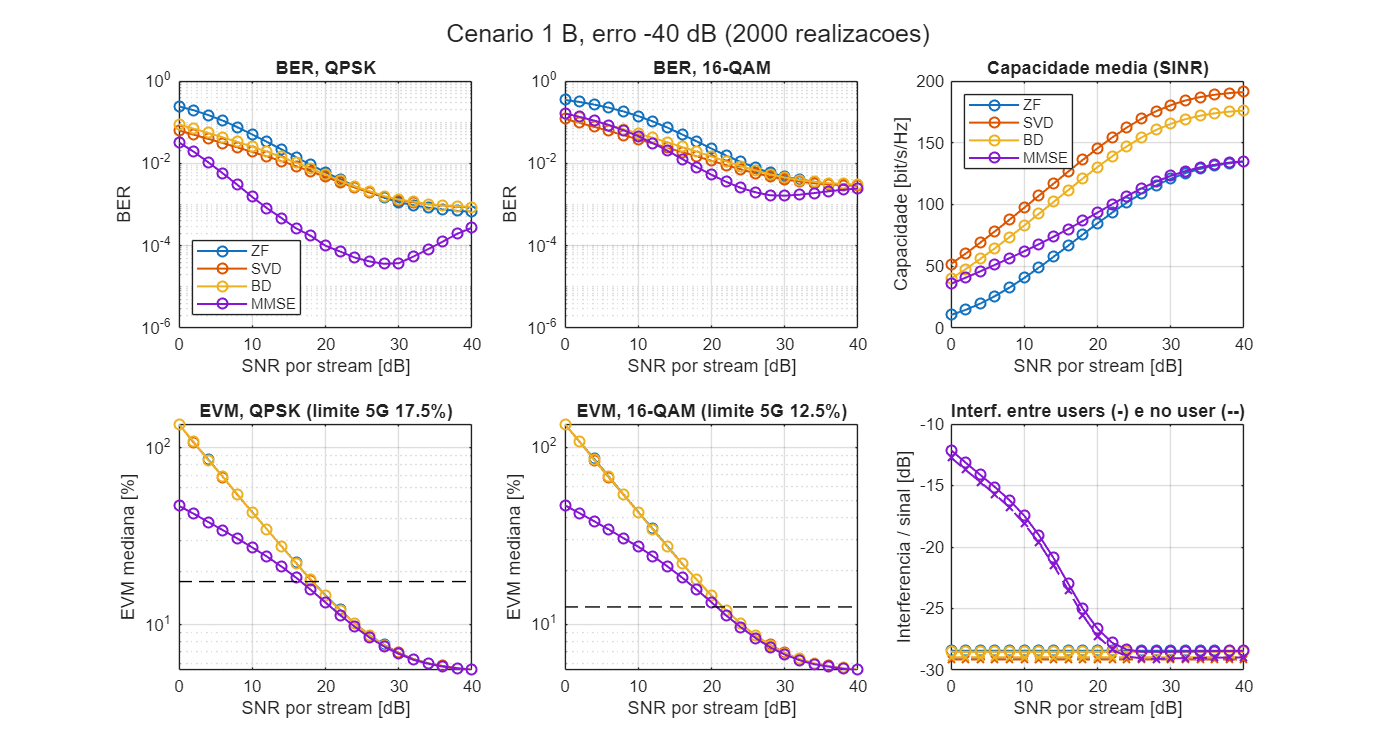

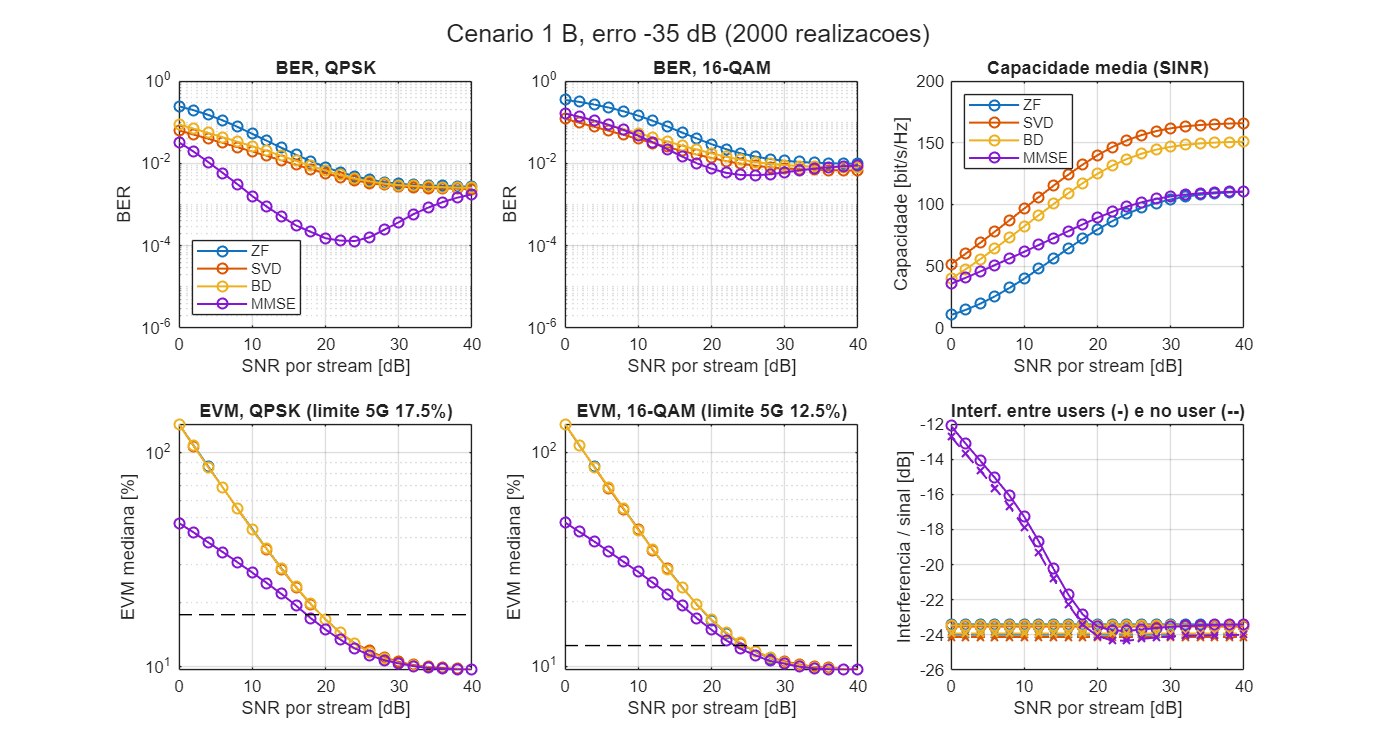

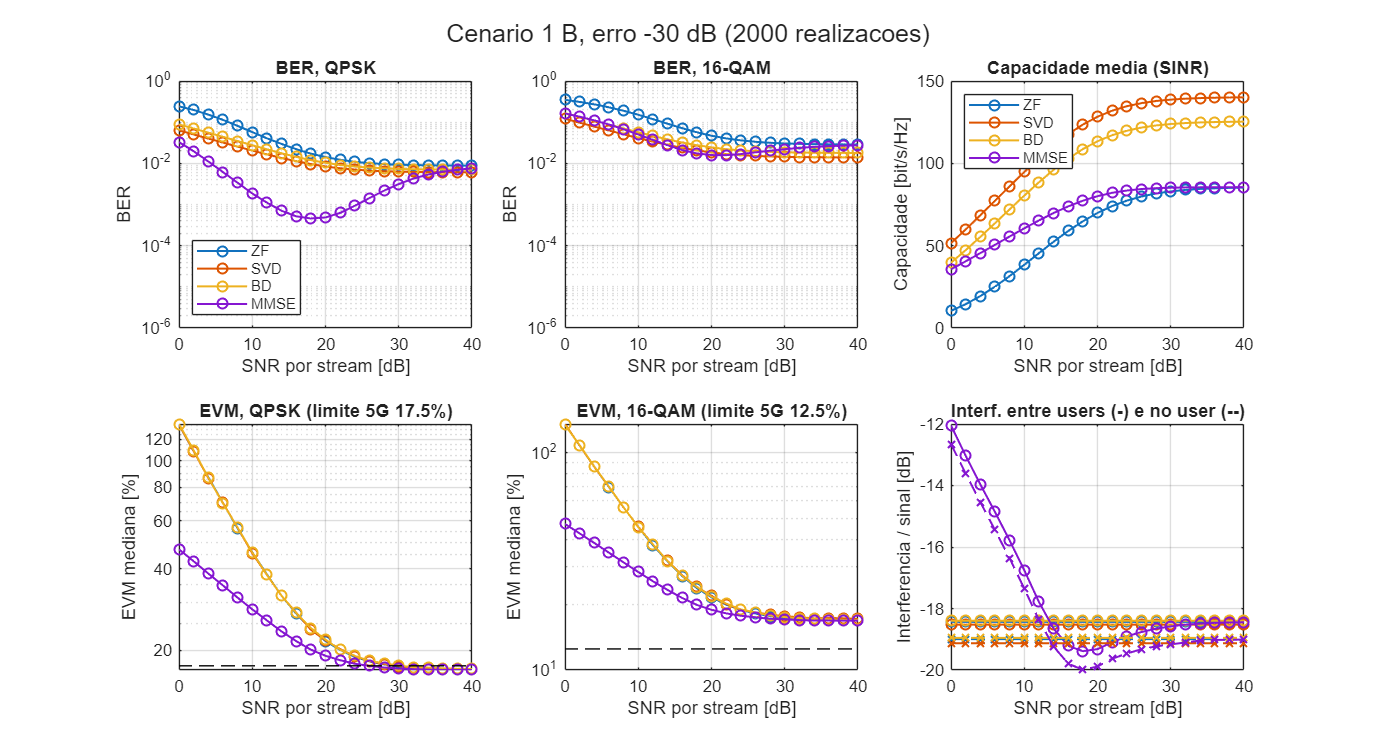

rng(1);
Nt = 16;  sizes = [8 8];
R4_1B = cell(1,3);  R16_1B = cell(1,3);
for L = 1:3
    sig_e2 = 10^(niveis12(L)/10);
    rng(1);  R4_1B{L}  = simula_cenario(Nt, sizes, D12, T12, snr_db, 4,  sig_e2);
    rng(1);  R16_1B{L} = simula_cenario(Nt, sizes, D12, T12, snr_db, 16, sig_e2);
    plota_fase2(R4_1B{L}, R16_1B{L}, snr_db, sprintf('Cenario 1 B, erro %d dB', niveis12(L)));
end

### Cenário 2 A

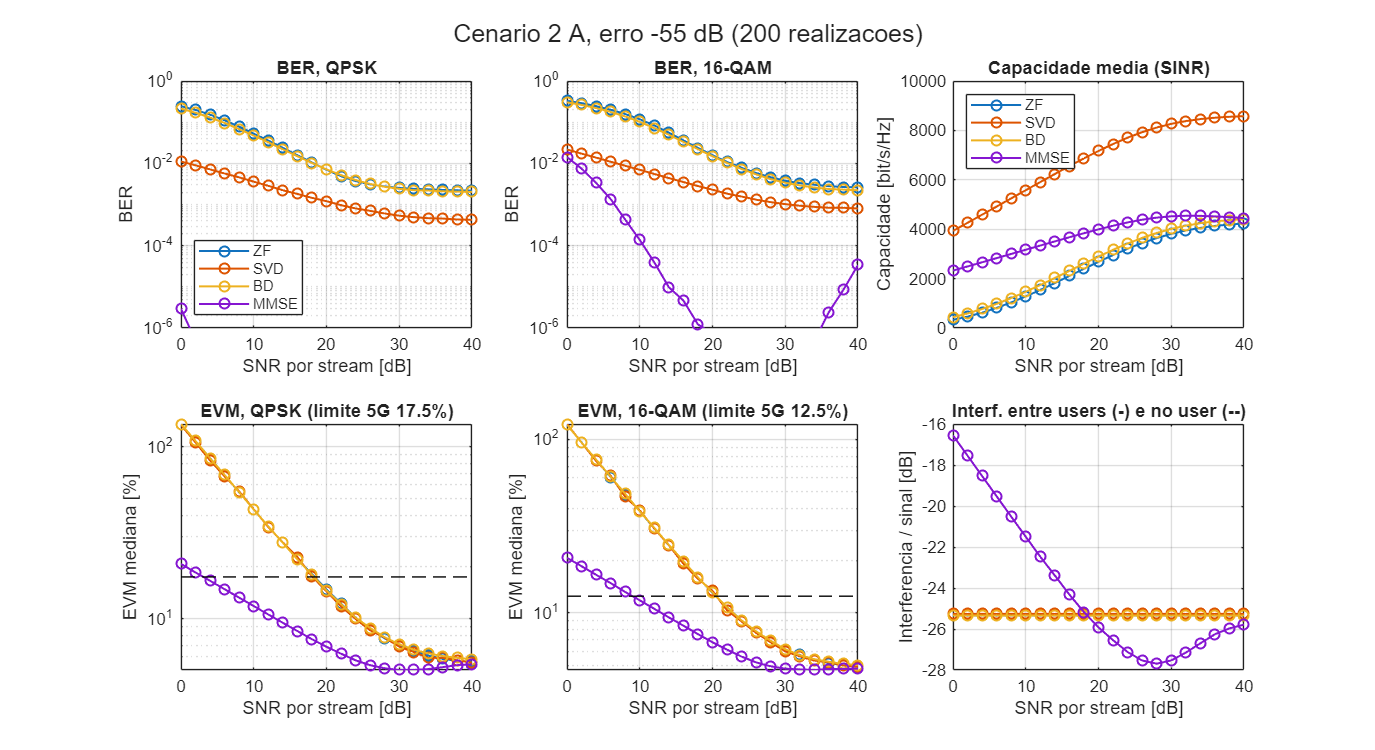

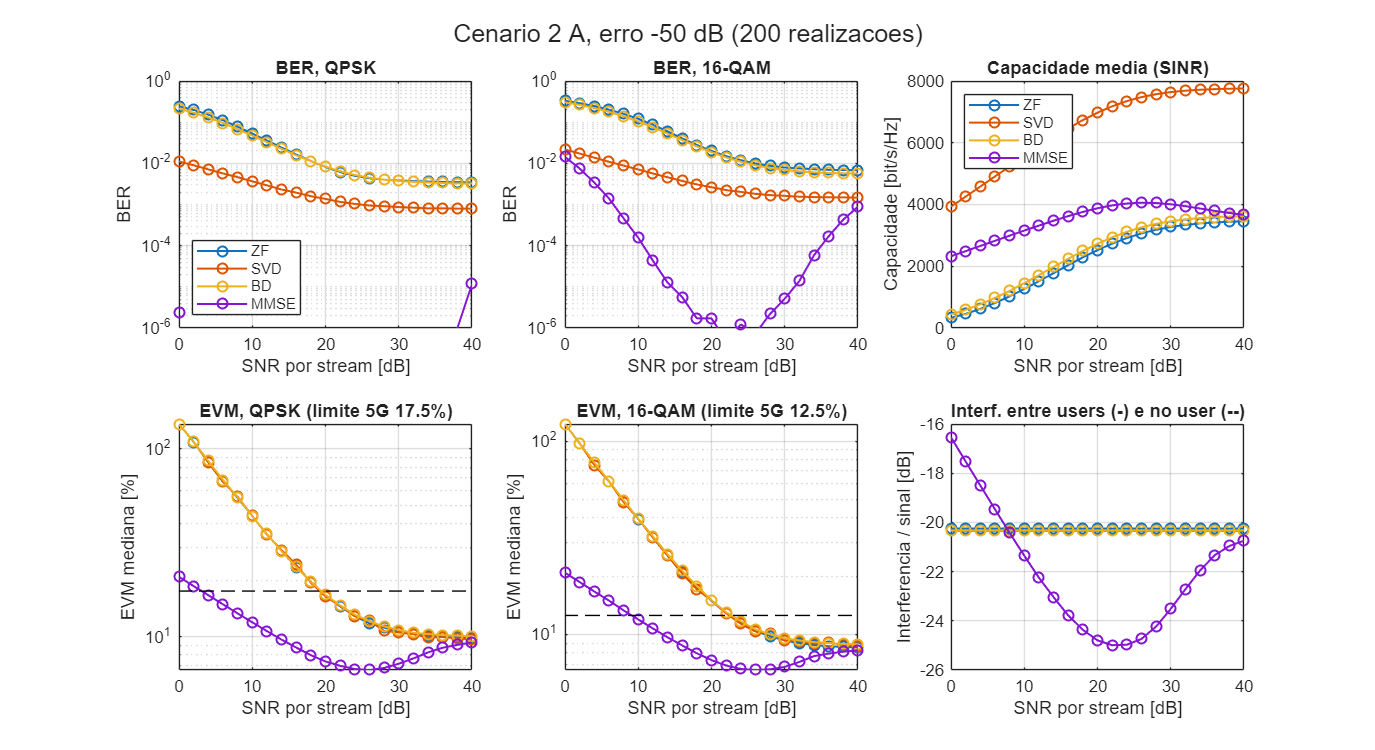

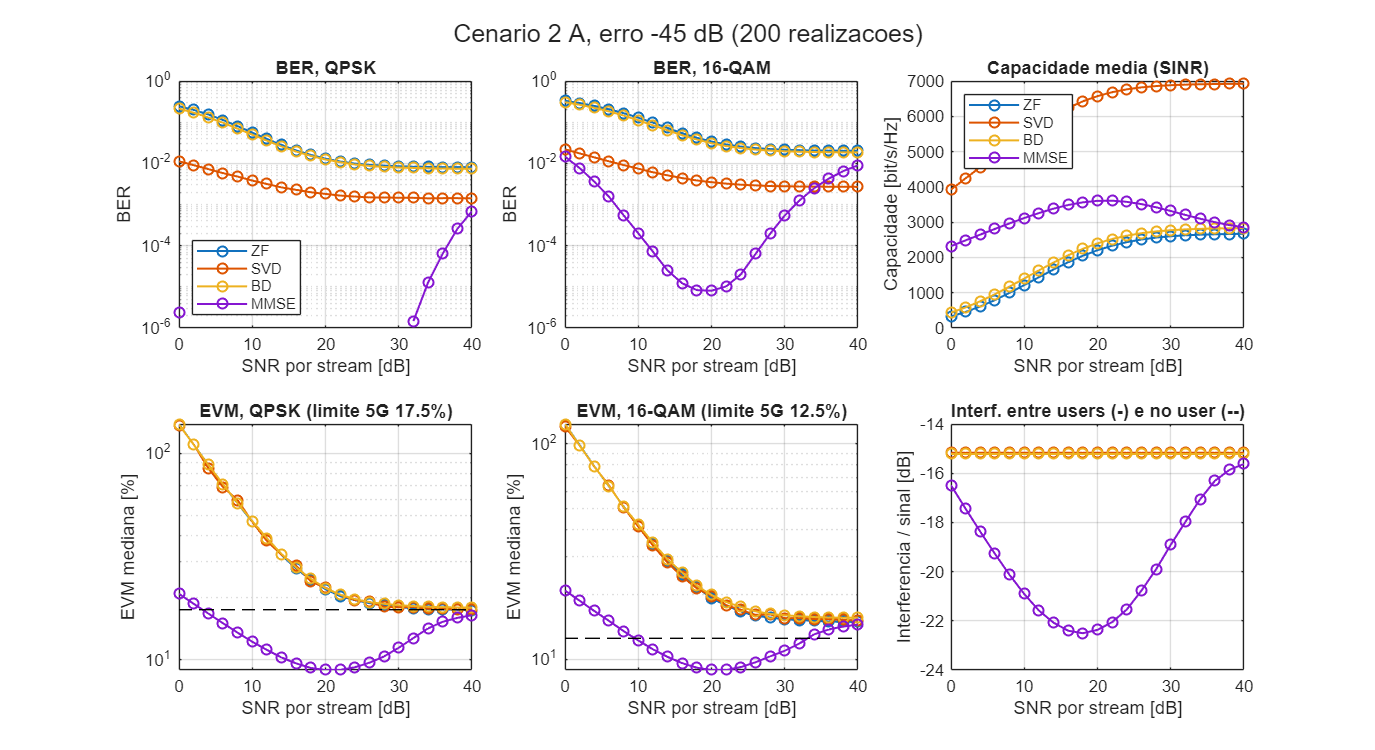

rng(1);
Nt = 512;  sizes = ones(1,512);
R4_2A = cell(1,3);  R16_2A = cell(1,3);
for L = 1:3
    sig_e2 = 10^(niveis512(L)/10);
    rng(1);  R4_2A{L}  = simula_cenario(Nt, sizes, D512, T512, snr_db, 4,  sig_e2);
    rng(1);  R16_2A{L} = simula_cenario(Nt, sizes, D512, T512, snr_db, 16, sig_e2);
    plota_fase2(R4_2A{L}, R16_2A{L}, snr_db, sprintf('Cenario 2 A, erro %d dB', niveis512(L)));
end

### Cenário 2 B

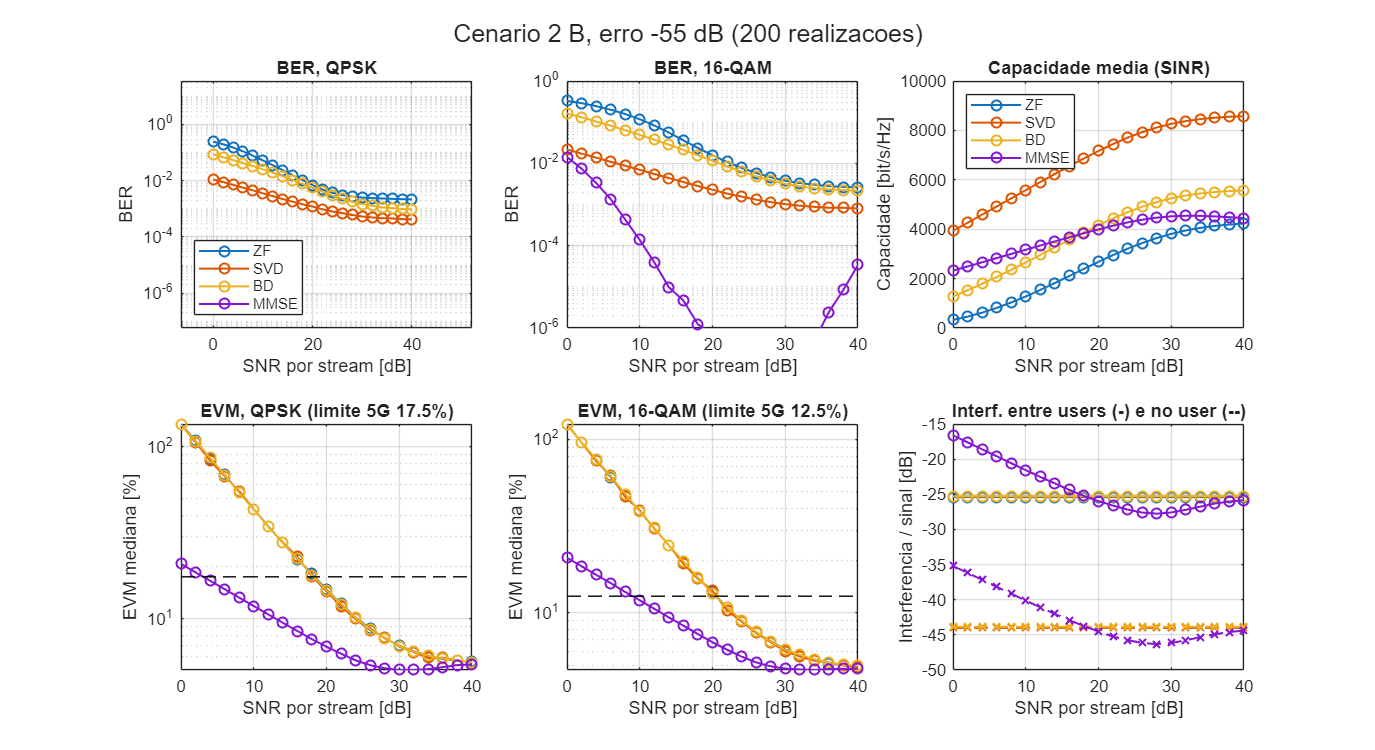

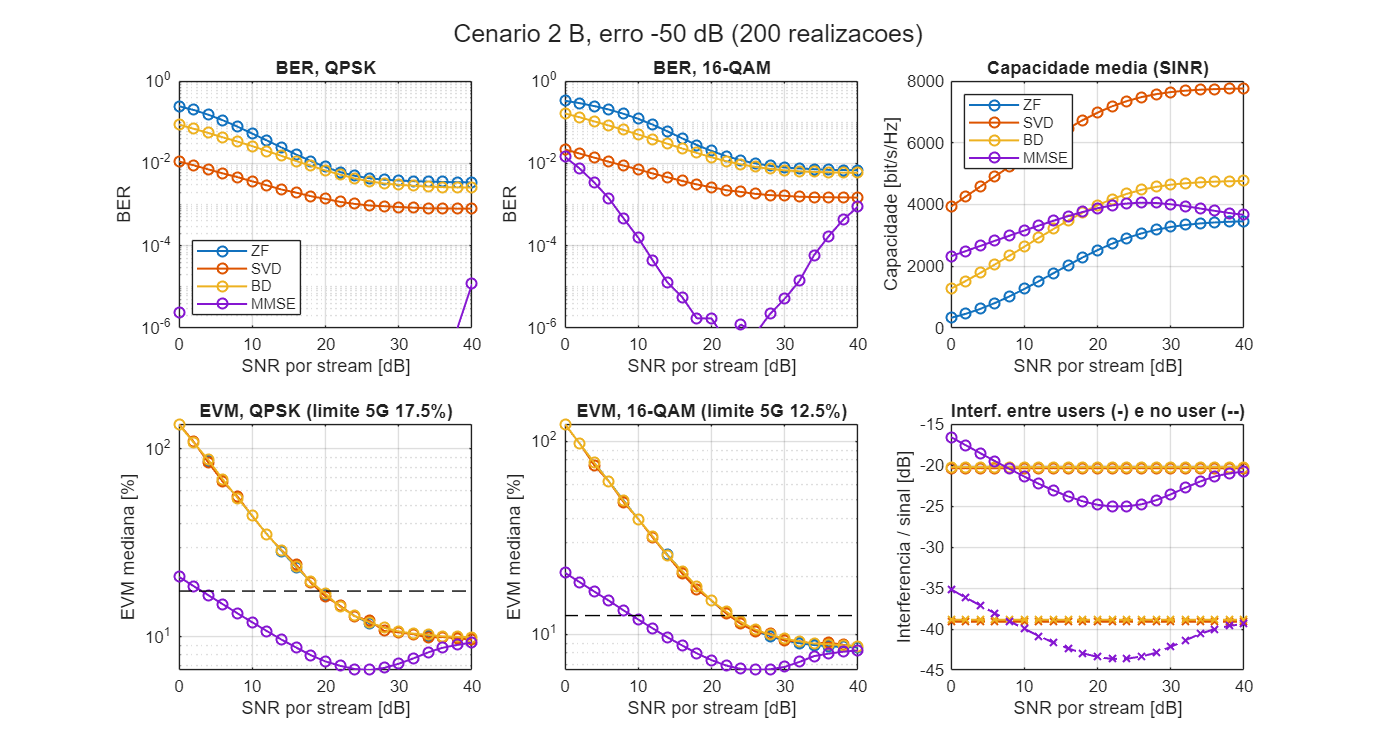

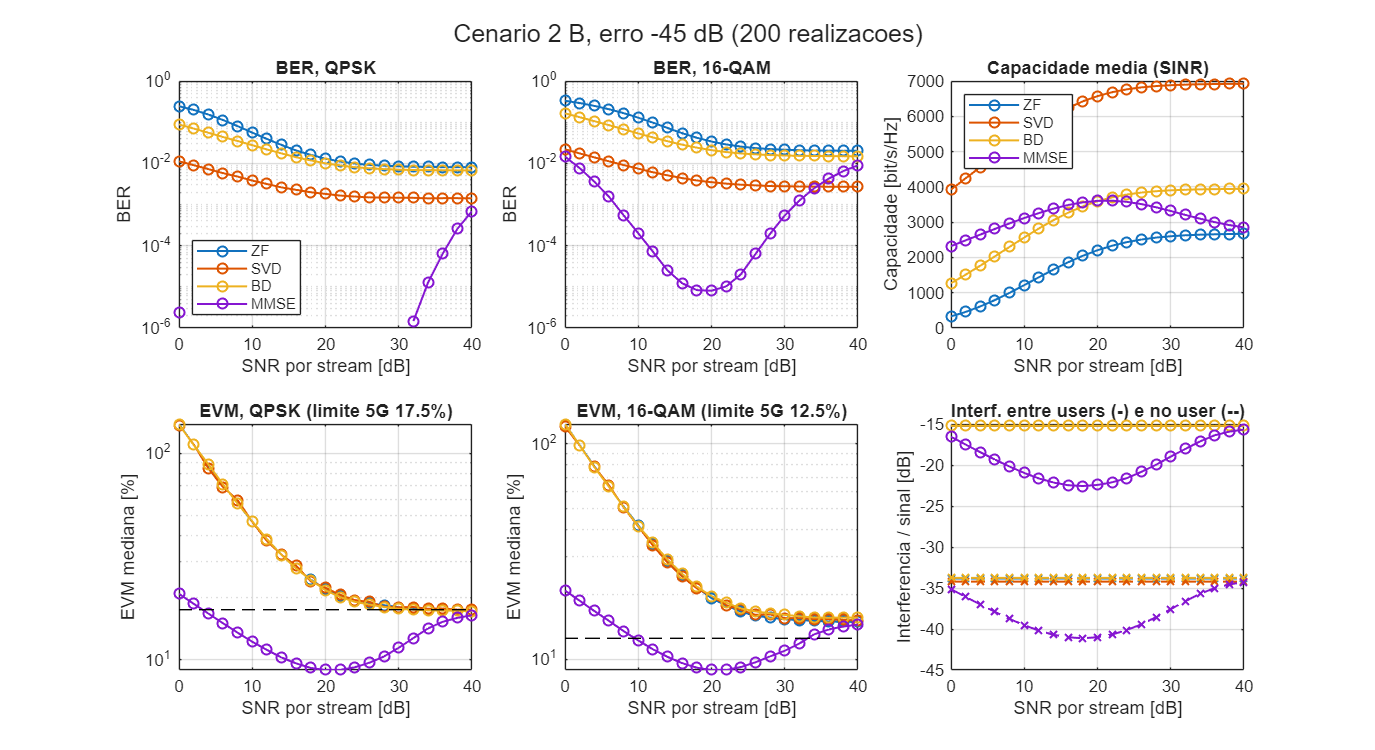

rng(1);
Nt = 512;  sizes = 8*ones(1,64);
R4_2B = cell(1,3);  R16_2B = cell(1,3);
for L = 1:3
    sig_e2 = 10^(niveis512(L)/10);
    rng(1);  R4_2B{L}  = simula_cenario(Nt, sizes, D512, T512, snr_db, 4,  sig_e2);
    rng(1);  R16_2B{L} = simula_cenario(Nt, sizes, D512, T512, snr_db, 16, sig_e2);
    plota_fase2(R4_2B{L}, R16_2B{L}, snr_db, sprintf('Cenario 2 B, erro %d dB', niveis512(L)));
end

# Tabelas da Fase 2

cen  = {'1A','1B','2A','2B'};
R4s  = {R4_1A,  R4_1B,  R4_2A,  R4_2B};
R16s = {R16_1A, R16_1B, R16_2A, R16_2B};
niv  = {niveis12, niveis12, niveis512, niveis512};
tec  = {'ZF','SVD','BD','MMSE'};
i20  = find(snr_db == 20);
for c = 1:4
    for L = 1:3
        r4 = R4s{c}{L};  r16 = R16s{c}{L};
        C20   = r4.C(i20,:);
        IUI20 = 10*log10(squeeze(median(r4.IUI(:,i20,:),1)))';
        smin4 = zeros(1,4);  smin16 = zeros(1,4);
        for k = 1:4
            smin4(k)  = cruza(snr_db, median(r4.EVM(:,:,k),1),  17.5);
            smin16(k) = cruza(snr_db, median(r16.EVM(:,:,k),1), 12.5);
        end
        Tab = array2table([C20; IUI20; smin4; smin16], 'VariableNames', tec, ...
              'RowNames', {'C_20dB','IUI_20dB','SNRmin_QPSK','SNRmin_16QAM'});
        fprintf('\nCenario %s, erro %d dB:\n', cen{c}, niv{c}(L));
        disp(Tab)
    end
end


Cenario 1A, erro -40 dB:


                      ZF        SVD        BD        MMSE  
                    ______    _______    _______    _______

    C_20dB          84.731     145.46     90.946     93.438
    IUI_20dB        -25.66    -25.679    -25.662    -23.861
    SNRmin_QPSK     18.256     18.188     18.252      16.63
    SNRmin_16QAM    21.544     21.542     21.545      20.71




Cenario 1A, erro -35 dB:


                      ZF        SVD        BD        MMSE  
                    ______    _______    _______    _______

    C_20dB          79.779     139.93     85.881     89.234
    IUI_20dB         -20.7    -20.678    -20.635    -20.726
    SNRmin_QPSK     19.381     19.373     19.383     17.432
    SNRmin_16QAM    24.425     24.497     24.249     23.205




Cenario 1A, erro -30 dB:


                      ZF         SVD        BD       MMSE  
                    _______    _______    ______    _______

    C_20dB           69.883     128.31    75.664     80.058
    IUI_20dB        -15.719    -15.749     -15.7    -16.595
    SNRmin_QPSK      29.266      29.85    29.228     25.979
    SNRmin_16QAM        NaN        NaN       NaN        NaN




Cenario 1B, erro -40 dB:


                      ZF         SVD        BD        MMSE  
                    _______    _______    _______    _______

    C_20dB           84.731     145.46     130.31     93.438
    IUI_20dB        -28.435    -28.525    -28.516    -26.641
    SNRmin_QPSK      18.256     18.188     18.252      16.63
    SNRmin_16QAM     21.544     21.542     21.555      20.71




Cenario 1B, erro -35 dB:


                      ZF         SVD        BD        MMSE  
                    _______    _______    _______    _______

    C_20dB           79.779     139.93     124.84     89.234
    IUI_20dB        -23.402    -23.526    -23.461    -23.522
    SNRmin_QPSK      19.381     19.373     19.364     17.432
    SNRmin_16QAM     24.425     24.497     24.577     23.205




Cenario 1B, erro -30 dB:


                      ZF         SVD        BD       MMSE 
                    _______    _______    ______    ______

    C_20dB           69.883     128.31    113.41    80.058
    IUI_20dB        -18.435    -18.526     -18.4    -19.32
    SNRmin_QPSK      29.266      29.85     30.28    25.979
    SNRmin_16QAM        NaN        NaN       NaN       NaN




Cenario 2A, erro -55 dB:


                      ZF        SVD        BD        MMSE  
                    _______    ______    _______    _______

    C_20dB           2680.4    7167.6     2891.2     3994.2
    IUI_20dB        -25.347    -25.26    -25.342    -25.922
    SNRmin_QPSK      18.367    18.071     18.266     3.0596
    SNRmin_16QAM     20.456    20.543      20.49     8.9971




Cenario 2A, erro -50 dB:


                      ZF         SVD        BD        MMSE  
                    _______    _______    _______    _______

    C_20dB           2522.2     6974.4     2728.6     3878.1
    IUI_20dB        -20.249    -20.343    -20.325    -24.796
    SNRmin_QPSK      19.413     19.221     19.417     3.0953
    SNRmin_16QAM     22.477     22.403     22.716     9.1246




Cenario 2A, erro -45 dB:


                      ZF        SVD        BD        MMSE  
                    ______    _______    _______    _______

    C_20dB          2204.1     6571.6     2398.3     3602.9
    IUI_20dB        -15.18    -15.167    -15.218    -22.368
    SNRmin_QPSK     36.843        NaN        NaN     3.2043
    SNRmin_16QAM       NaN        NaN        NaN     9.5554




Cenario 2B, erro -55 dB:


                      ZF         SVD        BD        MMSE 
                    _______    _______    _______    ______

    C_20dB           2680.4     7167.6     4161.5    3994.2
    IUI_20dB        -25.407    -25.317    -25.272    -25.98
    SNRmin_QPSK      18.367     18.071     18.223    3.0596
    SNRmin_16QAM     20.456     20.543     20.391    8.9971




Cenario 2B, erro -50 dB:


                      ZF         SVD        BD        MMSE  
                    _______    _______    _______    _______

    C_20dB           2522.2     6974.4     3975.5     3878.1
    IUI_20dB        -20.308    -20.399    -20.265    -24.856
    SNRmin_QPSK      19.413     19.221     19.542     3.0953
    SNRmin_16QAM     22.477     22.403     22.754     9.1246




Cenario 2B, erro -45 dB:


                      ZF         SVD        BD        MMSE 
                    _______    _______    _______    ______

    C_20dB           2204.1     6571.6     3592.3    3602.9
    IUI_20dB        -15.239    -15.232    -15.215    -22.43
    SNRmin_QPSK      36.843        NaN     31.912    3.2043
    SNRmin_16QAM        NaN        NaN        NaN    9.5554



# Pré-codificação

### ZF

Calcula W = Hᴴ (H Hᴴ)⁻¹, a matriz que anula a interferência entre streams

function W = zf_precoder(H)
W = H' / (H*H');
end

### SVD

SVD do canal completo: limite superior (receptores a cooperar)

function [W, G, s] = svd_precoder(H)
[U, S, V] = svd(H);
W = V;
G = U';
s = diag(S);
end

### Water-filling

Distribui a potência pelos canais para maximizar a capacidade

function p = water_filling(g, P)
% g: ganhos de potencia dos canais (sigma_i^2); P: potencia total (ruido unitario)
g = g(:);  n = numel(g);
[gs, ordem] = sort(g, 'descend');
inv_g = 1 ./ gs;
mu = (P + cumsum(inv_g)) ./ (1:n)';       % nivel de agua candidato com k canais
k  = find(mu > inv_g, 1, 'last');         % nº de canais activos
p = zeros(n,1);
p(ordem) = max(mu(k) - inv_g, 0);
end

### BD

Block Diagonalization: anula a interferência entre utilizadores, mas deixa a dos streams do mesmo user (que ele resolve com as suas antenas)

function [W, G, e] = bd_precoder(H, sizes, atalho)
% Block Diagonalization: W_j = V0_j * V1_j
%   V0_j : base do espaco nulo dos canais dos outros utilizadores
%   V1_j : SVD do canal efectivo H_j*V0_j
if nargin < 3, atalho = true; end        % atalho = false: BD classico (so para medir complexidade)
[Nrt, Nt] = size(H);
st = [0 cumsum(sizes)];
quadrada = atalho && (Nrt == Nt);
if quadrada, Hi = inv(H); end            % atalho: colunas de inv(H) geram o espaco nulo
W = [];  G = zeros(Nrt, Nrt);  e = [];  r = 0;
for j = 1:numel(sizes)
    a = st(j)+1;  b = st(j+1);
    Hj = H(a:b, :);                       % canal do user j
    if quadrada
        [V0, ~] = qr(Hi(:, a:b), 0);      % Hi(:,a:b) e ortogonal as linhas dos outros users
    else
        Ht = H([1:a-1, b+1:Nrt], :);      % canal dos outros users
        [~, ~, V] = svd(Ht);
        V0 = V(:, min(size(Ht))+1:end);   % espaco nulo de Ht
    end
    [U, S, V1] = svd(Hj*V0, 'econ');      % canal efectivo do user j
    s = diag(S);  L = numel(s);
    W = [W, V0*V1];                       %#ok<AGROW>
    e = [e; s];                           %#ok<AGROW>
    G(r+1:r+L, a:b) = U';
    r = r + L;
end
G = G(1:r, :);
end

### Modulação

function [u, bits] = mod_qam(Ns, T, M)
% Simbolos QAM Gray, potencia media 1 (M = 4: QPSK, M = 16: 16-QAM)
if M == 4
    bits = {randi([0 1],Ns,T), randi([0 1],Ns,T)};            % sinal de I e de Q
    u = ((1-2*bits{1}) + 1j*(1-2*bits{2})) / sqrt(2);
else
    bits = {randi([0 1],Ns,T), randi([0 1],Ns,T), randi([0 1],Ns,T), randi([0 1],Ns,T)};
    u = ((1-2*bits{1}).*(3-2*bits{3}) + 1j*(1-2*bits{2}).*(3-2*bits{4})) / sqrt(10);
end
end

function ne = conta_erros(uh, bits, M)
ne = sum(sum((real(uh) < 0) ~= bits{1})) + sum(sum((imag(uh) < 0) ~= bits{2}));
if M == 16
    ne = ne + sum(sum((abs(real(uh))*sqrt(10) < 2) ~= bits{3})) ...
            + sum(sum((abs(imag(uh))*sqrt(10) < 2) ~= bits{4}));
end
end

function p = ber_teo(g, M)
% BER teorica (AWGN, Gray) para SNR por simbolo g (potencia media 1)
if M == 4
    p = 0.5*erfc(sqrt(g/2));
else
    a = sqrt(g/10);
    p = 3/8*erfc(a) + 1/4*erfc(3*a) - 1/8*erfc(5*a);
end
end

function R = simula_cenario(Nt, sizes, D, T, snr_db, M, sig_e2)
Nrt = sum(sizes);  Ns = Nrt;  nS = numel(snr_db);
st = [0 cumsum(sizes)];
mesmo = false(Ns);                                   % streams do mesmo utilizador
for j = 1:numel(sizes), mesmo(st(j)+1:st(j+1), st(j)+1:st(j+1)) = true; end
dentro = mesmo & ~logical(eye(Ns));                  % outros streams do mesmo utilizador
fora   = ~mesmo;                                     % streams de outros utilizadores
erros = zeros(nS,4);  cap = zeros(nS,4);
EVMd  = zeros(D,nS,4);  IUI = zeros(D,nS,4);  ISI = zeros(D,nS,4);
for d = 1:D
    H  = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);
    Hh = H;                                          % estimativa do canal
    if sig_e2 > 0
        Hh = H + sqrt(sig_e2/2)*(randn(Nrt,Nt) + 1j*randn(Nrt,Nt));
    end
    W_zf = zf_precoder(Hh);
    [W_svd, G_svd, s]  = svd_precoder(Hh);
    [W_bd, G_bd, e_bd] = bd_precoder(Hh, sizes);
    HV  = H*W_svd;
    Aef = {H*W_zf, (G_svd*HV)./s, (G_bd*(H*W_bd))./e_bd, []};   % A = G*H*W (MMSE: por SNR)
    [u, bits] = mod_qam(Ns, T, M);
    for i = 1:nS
        snr_i  = 10^(snr_db(i)/10);
        n      = (randn(Nrt,T) + 1j*randn(Nrt,T)) / sqrt(2);
        beta2  = Ns*snr_i / norm(W_zf,'fro')^2;
        gm     = s ./ (s.^2 + 1/snr_i);              % MMSE: W = V*diag(gm)*U'
        beta2m = Ns*snr_i / sum(gm.^2);
        Aef{4} = (HV .* gm.') * G_svd;
        nv = {ones(Ns,1)/beta2, 1./(snr_i*s.^2), 1./(snr_i*e_bd.^2), ones(Ns,1)/beta2m};
        Y = cell(1,4);                               % sinal detectado = A*u + ruido equalizado
        Y{1} = Aef{1}*u + n/sqrt(beta2);
        Y{2} = Aef{2}*u + (G_svd*n)./(sqrt(snr_i)*s);
        Y{3} = Aef{3}*u + (G_bd *n)./(sqrt(snr_i)*e_bd);
        Y{4} = Aef{4}*u + n/sqrt(beta2m);
        for k = 1:4
            erros(i,k)  = erros(i,k) + conta_erros(Y{k}, bits, M);
            EVMd(d,i,k) = 100*sqrt(mean(abs(Y{k}(:) - u(:)).^2));
            [sinr, IUI(d,i,k), ISI(d,i,k)] = metricas_A(Aef{k}, nv{k}, dentro, fora);
            cap(i,k) = cap(i,k) + sum(log2(1 + sinr));
        end
    end
end
R.BER = erros / (log2(M)*Ns*T*D);
R.BER(R.BER == 0) = NaN;
R.C   = cap / D;
R.EVM = EVMd;
R.IUI = IUI;                                         % interferencia entre utilizadores / sinal
R.ISI = ISI;                                         % interferencia dentro do utilizador / sinal
R.sig_e2 = sig_e2;
end

function [sinr, iui, isi] = metricas_A(Aef, nv, dentro, fora)
% SINR por stream e razoes interferencia/sinal (potencia) a partir de A = G*H*W
% nv: potencia do ruido equalizado em cada stream
P     = abs(Aef).^2;
sig   = diag(P);
intra = sum(P.*dentro, 2);                           % outros streams do mesmo utilizador
inter = sum(P.*fora,   2);                           % streams de outros utilizadores
sinr  = sig ./ (intra + inter + nv);
iui   = sum(inter) / sum(sig);
isi   = sum(intra) / sum(sig);
end

function plota_fase2(R4, R16, snr_db, nome)
% 6 paineis: BER (QPSK, 16-QAM), capacidade, EVM (QPSK, 16-QAM), interferencia
D = size(R4.EVM, 1);
tec = {'ZF','SVD','BD','MMSE'};
figure('Name', nome, 'Position', [100 100 1100 600]);
subplot(2,3,1); semilogy(snr_db, R4.BER, 'o-', 'LineWidth', 1.2); grid on; ylim([1e-6 1]); yticks([1e-6 1e-4 1e-2 1]);
legend(tec, 'Location', 'southwest'); xlabel('SNR por stream [dB]'); ylabel('BER'); title('BER, QPSK');
subplot(2,3,2); semilogy(snr_db, R16.BER, 'o-', 'LineWidth', 1.2); grid on; ylim([1e-6 1]); yticks([1e-6 1e-4 1e-2 1]);
xlabel('SNR por stream [dB]'); ylabel('BER'); title('BER, 16-QAM');
subplot(2,3,3); plot(snr_db, R4.C, 'o-', 'LineWidth', 1.2); grid on;
legend(tec, 'Location', 'northwest'); xlabel('SNR por stream [dB]'); ylabel('Capacidade [bit/s/Hz]'); title('Capacidade media (SINR)');
subplot(2,3,4); semilogy(snr_db, squeeze(median(R4.EVM,1)), 'o-', 'LineWidth', 1.2); hold on;
plot(snr_db, 17.5*ones(size(snr_db)), 'k--'); grid on;
xlabel('SNR por stream [dB]'); ylabel('EVM mediana [%]'); title('EVM, QPSK (limite 5G 17.5%)');
subplot(2,3,5); semilogy(snr_db, squeeze(median(R16.EVM,1)), 'o-', 'LineWidth', 1.2); hold on;
plot(snr_db, 12.5*ones(size(snr_db)), 'k--'); grid on;
xlabel('SNR por stream [dB]'); ylabel('EVM mediana [%]'); title('EVM, 16-QAM (limite 5G 12.5%)');
subplot(2,3,6);
iui = squeeze(median(R4.IUI,1));  isi = squeeze(median(R4.ISI,1));
plot(snr_db, 10*log10(iui), 'o-', 'LineWidth', 1.2); hold on; grid on;
    if max(isi(:)) > 0                                   % so ha ISI quando os users tem varias antenas
        set(gca, 'ColorOrderIndex', 1);
        plot(snr_db, 10*log10(isi), 'x--', 'LineWidth', 1.2);
    end
xlabel('SNR por stream [dB]'); ylabel('Interferencia / sinal [dB]');
title('Interf. entre users (-) e no user (--)');
    if exist('sgtitle', 'file'), sgtitle(sprintf('%s (%d realizacoes)', nome, D)); end
end

function t = mede_complexidade(Nt, sizes, nrep, com_bd_classica)
% Tempo medio [ms] por subportadora (uma matriz H) de cada pre-codificador
Nrt = sum(sizes);
H = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);
zf_precoder(H); svd_precoder(H); bd_precoder(H, sizes);          % aquecimento
t = nan(1,4);                                                    % ZF | SVD | BD rapida | BD classica
tic; for r = 1:nrep, zf_precoder(H);        end; t(1) = 1e3*toc/nrep;
tic; for r = 1:nrep, svd_precoder(H);       end; t(2) = 1e3*toc/nrep;
tic; for r = 1:nrep, bd_precoder(H, sizes); end; t(3) = 1e3*toc/nrep;
    if com_bd_classica
        tic; bd_precoder(H, sizes, false);      t(4) = 1e3*toc;      % 1 repeticao
    end
end

function s = cruza(snr_db, m, lim)
% SNR a que a mediana do EVM cruza o limite (interpolacao linear em log10(EVM))
i = find(m < lim, 1);
    if isempty(i)
        s = NaN;
        elseif i == 1
            s = snr_db(1);
        else
            x0 = log10(m(i-1));  x1 = log10(m(i));
            s = snr_db(i-1) + (log10(lim) - x0) * (snr_db(i) - snr_db(i-1)) / (x1 - x0);
    end
end